# MA431 - Project 4

## Model the following system by using a second order DE

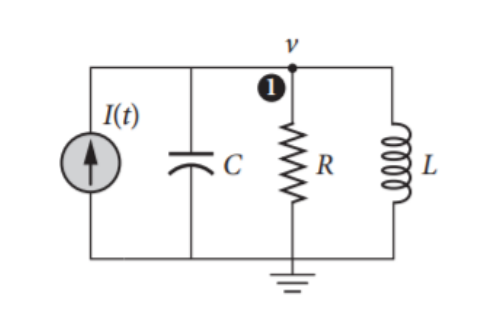

#### 1. Assign some realistic values to the system's parameters, provide references for them.

clc; clear all; close all;
L = 142*10^-3; % H
C = 160*10^-6; % F
R = 300; % Ohm

syms iL  s
I = 1/s^3

$$I = \frac{1}{s^{3}}$$

eq = iL == ((I)/(L*C))/(s^2 + s/(R*C) + 1/(L*C))

$$eq = \mathrm{iL}=\frac{18446744073709551616}{419110025354681\,s^{3}\,\left(s^{2}+\frac{125\,s}{6}+\frac{6049249712676057}{137438953472}\right)}$$

ilaplace(eq)

$$ans = \mathrm{iL}\,\delta (t)=\frac{18783630733578831423800966909999129252393130632977183670272\,{\mathrm{e}}^{-\frac{125\,t}{12}}\,\left(\cos\left(\frac{\sqrt{2}\,\sqrt{54309029686084513}\,t}{1572864}\right)+\frac{1333599201937436991488000\,\sqrt{2}\,\sqrt{54309029686084513}\,\sin\left(\frac{\sqrt{2}\,\sqrt{54309029686084513}\,t}{1572864}\right)}{2927603001720956446995173586447169}\right)}{834978122498115782293830132474994801708649681210299781226333897}-\frac{21778071482940061661655974875633165533184000\,t}{46010010175225491057654923991401363002733827707}+\frac{1267650600228229401496703205376\,t^{2}}{2535301200456459003513081572817}-\frac{18783630733578831423800966909999129252393130632977183670272}{834978122498115782293830132474994801708649681210299781226333897}$$

vpa(ilaplace(eq))

$$ans = \mathrm{iL}\,\delta (t)=0.000022495955555555551339102247051738\,{\mathrm{e}}^{-10.416666666666666666666666666667\,t}\,\left(\cos\left(209.53657810176679005134087041953\,t\right)+0.15012885168247634496079027626955\,\sin\left(209.53657810176679005134087041953\,t\right)\right)-0.00047333333333333324409983812556629\,t+0.49999999999999996045446688425754\,t^{2}-0.000022495955555555551339102247051738$$


t = 0;
dt = 10^-4;
simTime = 1;
idx = 1;
U = 0;
iL = 0;
while(t <= simTime)
    I = 1/2*t^2;
%     iL = (2.2699836e-5*cos(209.7720641*t))/(2.718281828^(3.125*t)) + (1.01508744e-6*sin(209.7720641*t))/(2.718281828^(3.125*t))+0.5*t^2-1.42e-4*t-2.2699836e-5;
%     if(iL > 100)
%         iL = 100;
%     end

if (I > 0.06)
    I = 0.06;
end
    iLDot = 1/L * U;
    uDot = 1/C * (I-iL-U/R);
    t_plt(idx) = t;
    iL_plt(idx) = iL;
    U_plt(idx) = U;

    U = U + uDot * dt;
    iL = iL + iLDot*dt;

    t = t + dt;
    idx = idx + 1;

end

fig = figure;
plot(t_plt,iL_plt, 'b', 'LineWidth', 2)
title("Current in Inductor", 'Interpreter', 'latex')
xlabel("Time [s]", 'Interpreter', 'latex')
ylabel("Ampere [A]", 'Interpreter', 'latex')
set(gca,'TickLabelInterpreter','latex')
legend("$i_L(t)$", 'Interpreter', 'latex')
grid
filename = "numerical_current_inductor.eps"

filename = "numerical_current_inductor.eps"

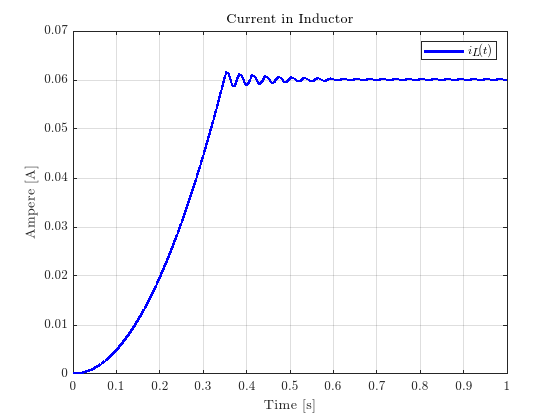

saveas(fig,filename, 'epsc')



fig = figure;
plot(t_plt, U_plt, 'r', 'LineWidth', 2)
title("Voltage of Capacitor", 'Interpreter', 'latex')
xlabel("Time [s]", 'Interpreter', 'latex')
ylabel("Ampere [A]", 'Interpreter', 'latex')
set(gca,'TickLabelInterpreter','latex')
legend("$i_L(t)$", 'Interpreter', 'latex')
grid
filename = "numerical_voltage_capacitor.eps"

filename = "numerical_voltage_capacitor.eps"

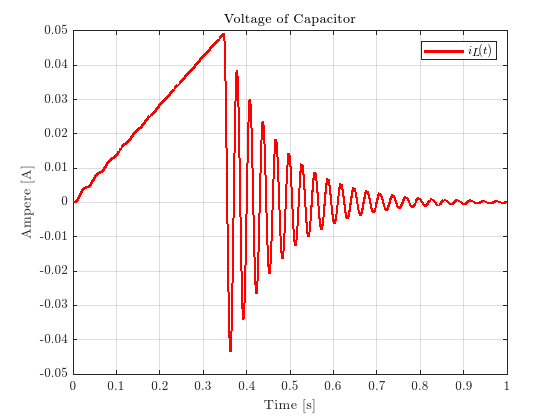

saveas(fig,filename, 'epsc')